# Evlaución de las capacidades de robot Scara

## Resumen

## Defición de la tarea

El robot debe lleva su efector final de un punto a un punto

% Definicion de los puntos

x_in = 0.3;
y_in = 0.3;
theta_in = 0; 

x_fin = 0.3;
y_fin = -0.3;
theta_fin = pi/2;

### Definición de la tarea en el espacio de las juntas

Para clacular la planeación de movimientos en el espacio de las juntas se requiere caluleos la postura en punto inicial y en punto final. 

% Cálculo de la solución de la primer postura

% Definición de los parámetros del robot
L1 = 0.5; % Longitud del primer eslabón
L2 = 0.5; % Longitud del segundo eslabón
L3 = 0.25; % Longitud del tercer eslabón

% Planteamiento de la solucion

x_3 = x_in - L3*cos(theta_in);
y_3 = y_in - L3*sin(theta_in);

% Solucion por le metodo geometrico

theta_2_in = acos((x_3^2+y_3^2-L1^2-L2^2)/(2*L1*L2));

beta = atan2(y_3,x_3);

psi = acos((x_3^2+y_3^2+L1^2-L2^2)/(2*L1*sqrt(x_3^2+y_3^2)));

theta_1_in = beta + psi;

% theta_1_in = beta - psi

theta_3_in = theta_in -theta_1_in - theta_2_in;


%%%
%% Solucion para el punto final


x_3 = x_fin - L3*cos(theta_fin);
y_3 = y_fin - L3*sin(theta_fin);

% Solucion por le metodo geometrico

theta_2_fin = acos((x_3^2+y_3^2-L1^2-L2^2)/(2*L1*L2));

beta = atan2(y_3,x_3);

psi = acos((x_3^2+y_3^2+L1^2-L2^2)/(2*L1*sqrt(x_3^2+y_3^2)));

theta_1_fin = beta + psi;

% theta_1_fin = beta - psi

theta_3_fin = theta_fin -theta_1_fin - theta_2_fin;



## Plateamiento de una trayectoria en el espacio de las juntas del robot

Definición de la trayectoria


$$q =q_i +\lambda \left(t\right)\left(q_{\mathrm{fin}} -q_{\mathrm{in}} \right)$$


tf = 10;
t = 0;


for i=1:tf
    t = t + 1; % Increment time for the next iteration
    theta_1_P(i) = theta_1_in + ((10/tf^3)*t^3 - (15/tf^4)*t^4 + (6/tf^5)*t^5)*(theta_1_fin-theta_1_in);
    theta_2_P(i) = theta_2_in + ((10/tf^3)*t^3 - (15/tf^4)*t^4 + (6/tf^5)*t^5)*(theta_2_fin-theta_2_in);
    theta_3_P(i) = theta_3_in + ((10/tf^3)*t^3 - (15/tf^4)*t^4 + (6/tf^5)*t^5)*(theta_3_fin-theta_3_in);
    
end



## Planeación de trayectoria en el espacio de trabajo del robot

% Cálculo de la solución de la primer postura

% Definición de los parámetros del robot
L1 = 0.5; % Longitud del primer eslabón
L2 = 0.5; % Longitud del segundo eslabón
L3 = 0.25; % Longitud del tercer eslabón


x_in = 0.3;
y_in = 0.3;
theta_in = 0; 

x_fin = 0.3;
y_fin = -0.3;
theta_fin = pi/2;
t = 0

t = 0

tf = 10;
for i=1:tf
    t = t + 1;
    x_P(i) = x_in + ((10/tf^3)*t^3 - (15/tf^4)*t^4 + (6/tf^5)*t^5)*(x_fin-x_in);
    y_P(i) = y_in + ((10/tf^3)*t^3 - (15/tf^4)*t^4 + (6/tf^5)*t^5)*(y_fin-y_in);
    theta_P(i) = theta_in + ((10/tf^3)*t^3 - (15/tf^4)*t^4 + (6/tf^5)*t^5)*(theta_fin-theta_in);

    x_3_a(i) = x_P(i) - L3*cos(theta_P(i));
    y_3_a(i) = y_P(i) - L3*sin(theta_P(i));

    % Solucion por le metodo geometrico

    theta_2_tray(i) = acos((x_3_a(i)^2+y_3_a(i)^2-L1^2-L2^2)/(2*L1*L2));

    beta = atan2(y_3_a(i),x_3_a(i));

    psi = acos((x_3_a(i)^2+y_3_a(i)^2+L1^2-L2^2)/(2*L1*sqrt(x_3_a(i)^2+y_3_a(i)^2)));

    theta_1_tray(i) = beta + psi;

    % theta_1_in = beta - psi

    theta_3_tray(i) = theta_P(i) - theta_1_tray(i) - theta_2_tray(i);

end


tsim=1:1:tf

tsim =      1     2     3     4     5     6     7     8     9    10


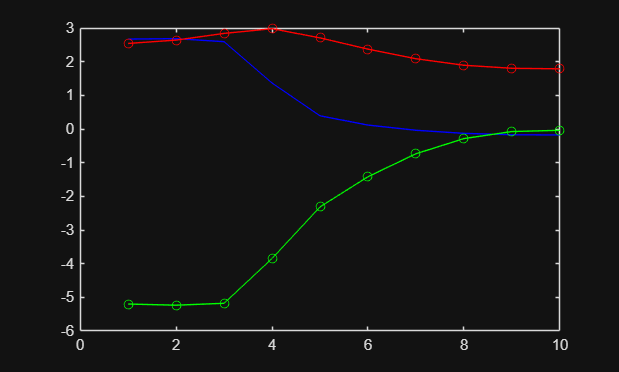

figure;

plot(tsim, theta_1_tray, 'b-');
hold on;
plot(tsim, theta_2_tray, 'r-o');
plot(tsim, theta_3_tray, 'g-o');

hold off;

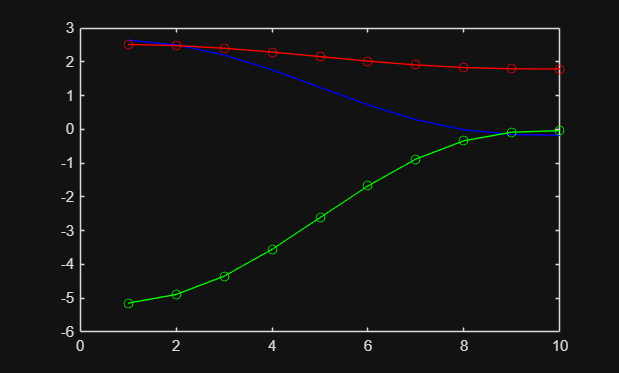




figure;

plot(tsim, theta_1_P, 'b-');
hold on;
plot(tsim, theta_2_P, 'r-o');
plot(tsim, theta_3_P, 'g-o');

hold off;


w = L1*L2*sin(theta_2)

